# Direct dynamics problem based on Virtual Power Equations using a Naive algorithm

## Related Slides

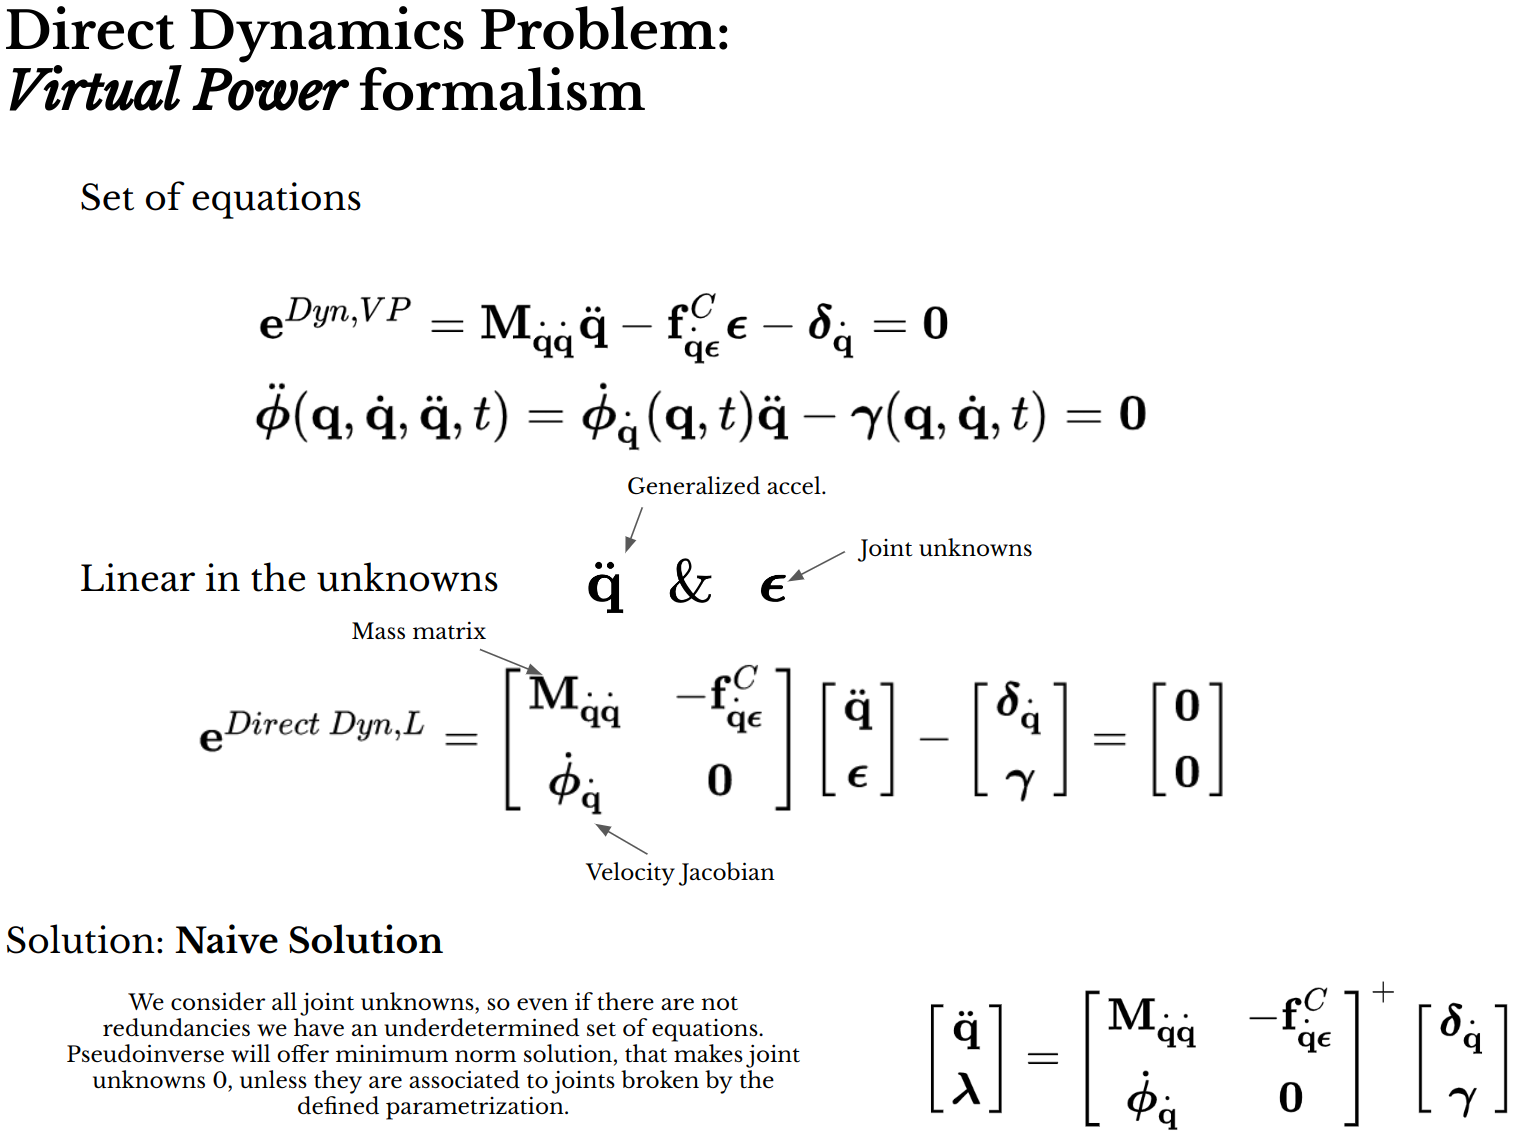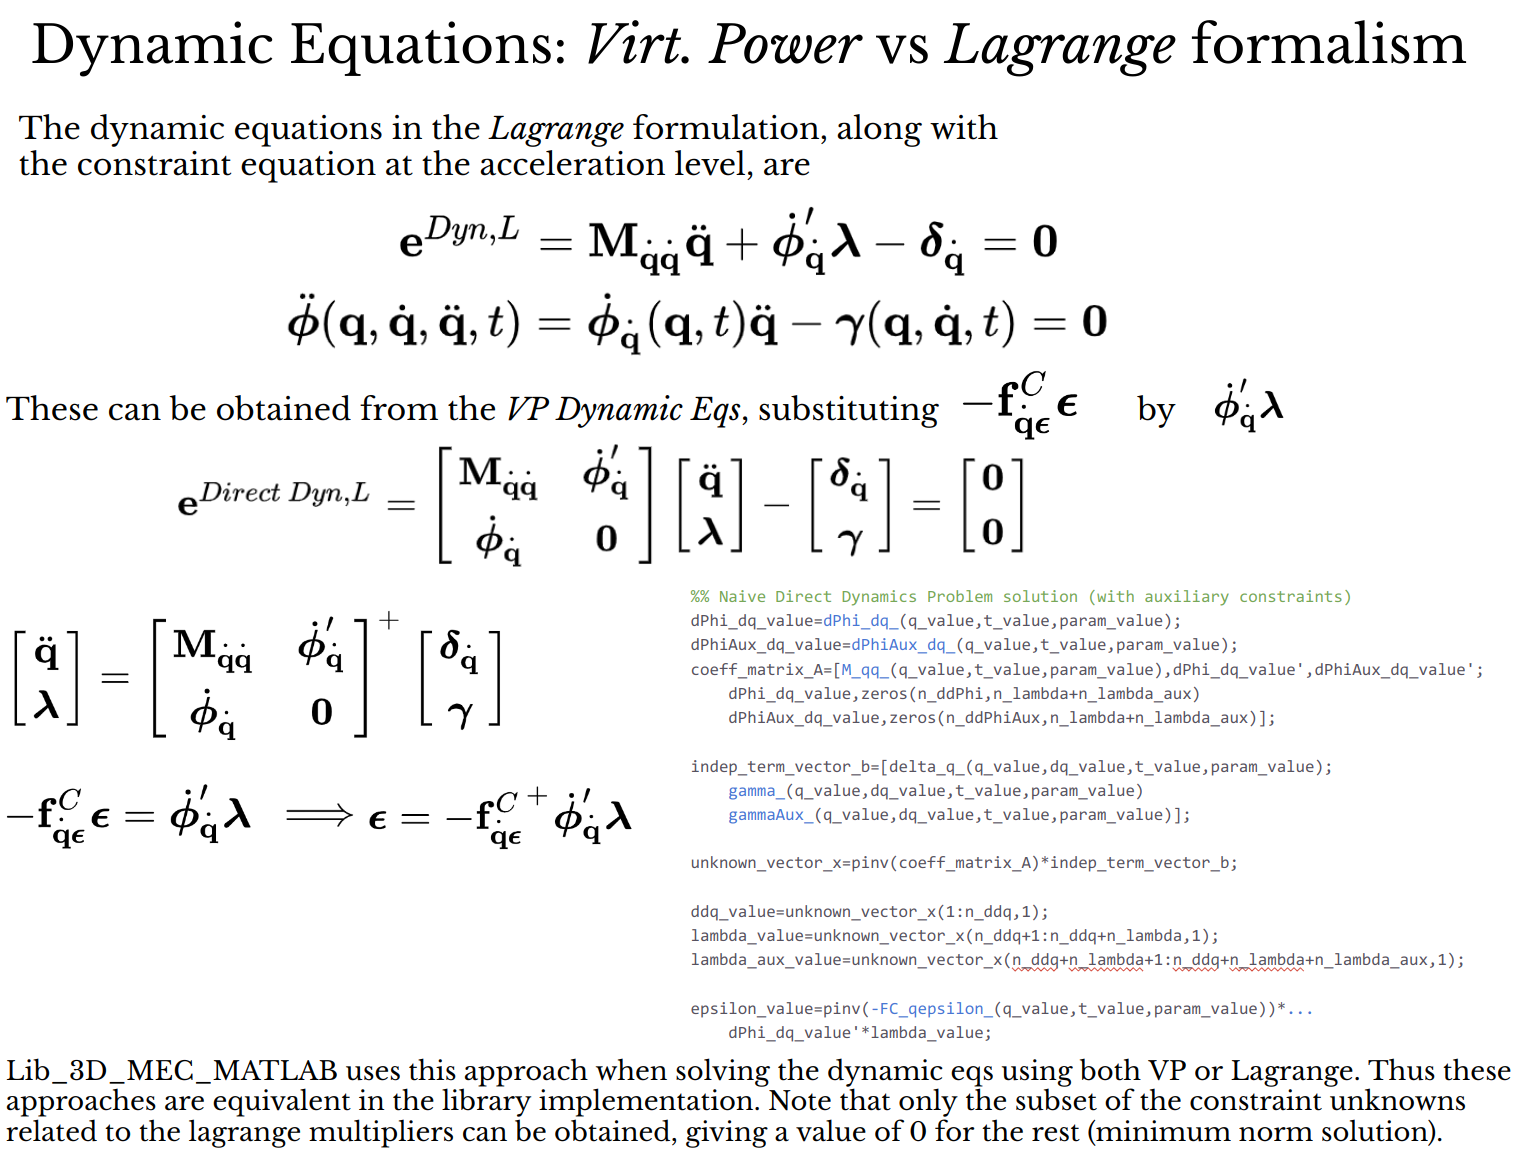

## Commented code:

Solve $\mathbf{e}^{D y n, L}=\mathbf{0}$ along with $\ddot{\mathbf{\phi}}=\mathbf{0}$ for $\ddot{\mathbf{q}}$ and$\mathbf{\lambda}$ and get the subset of $\mathbf{\epsilon}$ determinable from $\mathbf{\lambda}$ using the a trivial (Naive) algorithm.  These equations (in the Lagrange form) are assembled in a full linear system of equations that is solved using the pseudoinverse. This avoids problems associated to dependent/zero constraint equations and redundant constraint forces. Out from $\mathbf{\lambda}$ a minimum norm solution is given for the not fully determined subset of the constraint unknowns vector $\mathbf{\epsilon}$.

function [ddq_value,epsilon_value]=ddq_lambda_epsilon_from_Lagrange_Naive(q_value, dq_value, t_value, param_value)

global lambda_value
global n_ddq 
global n_dPhi n_ddPhi
global compute_all_epsilon_in_VP

Virtual power Dynamic equations along with constraint equations at the acceleration level:


$$$\mathbf{e}^{D y n, VP}=\mathbf{M}_{\dot{\mathbf{q}} \dot{\mathbf{q}}} \ddot{\mathbf{q}}-\mathbf{f}_{\dot{\mathbf{q}} {\mathbf{\epsilon}}}^C \mathbf{\epsilon}-\mathbf{\delta}_{\dot{\mathbf{q}}}=\mathbf{0}$$$



$$$\ddot{\phi}(\mathbf{q}, \dot{\mathbf{q}}, \ddot{\mathbf{q}}, t)=\dot{\phi}_{\dot{\mathbf{q}}}(\mathbf{q}, t) \ddot{\mathbf{q}}-\gamma(\mathbf{q}, \dot{\mathbf{q}}, t)=\mathbf{0}$$$


are solved for $\ddot{\mathbf{q}}$ and $\mathbf{\epsilon}$. To this end we use the Lagrange eqautions, 


$$$\left[\begin{array}{cc}\mathbf{M}_{\mathbf{v}} & \dot{\phi}_{\dot{\mathbf{q}}}^T \\ \dot{\phi}_{\dot{\mathbf{q}}} & \mathbf{0}\end{array}\right]\left[\begin{array}{l}\ddot{\mathbf{q}} \\ \mathbf{\lambda}\end{array}\right]+\left[\begin{array}{c}-\mathbf{\delta}_{\dot{\mathbf{q}}} \\ -\mathbf{\gamma}\end{array}\right]=\left[\begin{array}{l}\mathbf{0} \\ \mathbf{0}\end{array}\right]$$$


by the most trivial algorithm:


$$$\left[\begin{array}{c}\ddot{\mathbf{q}} \\ \mathbf{\lambda}\end{array}\right]=\left[\begin{array}{cc}\mathbf{M}_{\mathbf{v} \dot{\mathbf{q}}} & \dot{\phi}_{\dot{\mathbf{q}}}^T  \\ \dot{\phi}_{\dot{\mathbf{q}}} & \mathbf{0}\end{array}\right]^{+}\left[\begin{array}{c}\mathbf{\delta}_{\dot{\mathbf{q}}} \\ \mathbf{\gamma}\end{array}\right]$$$


and  obtain the determined subset of the constraint unknowns vector $\mathbf{\epsilon}$ out from $\mathbf{\lambda}$ as


$$\mathbf{f}^C_{\dot{\mathbf{q}}\mathbf{\epsilon}} \mathbf{\epsilon}=-\dot{\mathbf{\phi}}_{\dot{\mathbf{q}}}^\top\mathbf{\lambda}$$



$$\mathbf{\epsilon}=-\left[{\mathbf{f}_{\dot{\mathbf{q}},\mathbf{\epsilon}}^C}\right]^+ \dot{\mathbf{\phi}}_\dot{\mathbf{q}}^T \mathbf{\lambda}}$$


dPhi_dq_value=dPhi_dq_(q_value,t_value,param_value);
coeff_matrix_A=[M_qq_(q_value,t_value,param_value),dPhi_dq_value';
    dPhi_dq_value,zeros(n_ddPhi,n_dPhi)];

indep_term_vector_b=[delta_q_(q_value,dq_value,t_value,param_value);
    gamma_(q_value,dq_value,t_value,param_value)];

unknown_vector_x=pinv(coeff_matrix_A)*indep_term_vector_b;

ddq_value=unknown_vector_x(1:n_ddq,1);
lambda_value=unknown_vector_x(n_ddq+1:n_ddq+n_dPhi,1);

if compute_all_epsilon_in_VP==false
    %old
    epsilon_value=pinv(-FC_qepsilon_(q_value,t_value,param_value))*dPhi_dq_value'*lambda_value;

    %new


$$\left[ \begin{array}{c} \mathbf{f}^C_{\dot{\mathbf{q}}\mathbf{\epsilon}}\\ \mathbf{f}^C_{\dot{\mathbf{q}}^\perp\mathbf{\epsilon}} \end{array} \right] \mathbf{\epsilon} = \left[ \begin{array}{c} -\dot{\mathbf{\phi}}_{\dot{\mathbf{q}}}^\top\mathbf{\lambda}\\ \mathbf{M}_{\dot{\mathbf{q}}^\perp\ddot{\mathbf{q}}} \ddot{\mathbf{q}} - \mathbf{\delta}_{\dot{\mathbf{q}}^\perp} \end{array} \right]$$
 


$$\mathbf{\epsilon} = \left(\left[ \begin{array}{c} \mathbf{f}^C_{\dot{\mathbf{q}}\mathbf{\epsilon}}\\ \mathbf{f}^C_{\dot{\mathbf{q}}^\perp\mathbf{\epsilon}} \end{array} \right]\right)^+ \left[ \begin{array}{c} -\dot{\mathbf{\phi}}_{\dot{\mathbf{q}}}^\top\mathbf{\lambda}\\ \mathbf{M}_{\dot{\mathbf{q}}^\perp\ddot{\mathbf{q}}} \ddot{\mathbf{q}} - \mathbf{\delta}_{\dot{\mathbf{q}}^\perp} \end{array} \right]$$


else
    epsilon_value=pinv([FC_dq_epsilon_(q_value,t_value,param_value); ...
        FC_dq_orth_epsilon_(q_value,t_value,param_value)])*...
        [-dPhi_dq_value'*lambda_value;
        M_dq_orth_ddq_(q_value,t_value,param_value)*ddq_value-delta_dq_orth_(q_value,dq_value,t_value,param_value)];

end
end